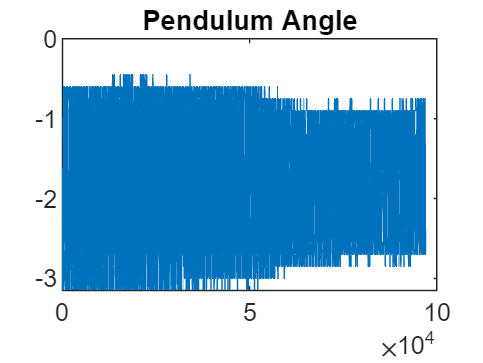

clear
close all
load("LinkedPendulum_NoInput.mat");

x = pendulum_angle(1000:98000);
y = rotor_angle(1000:98000);

plot(x);
title("Pendulum Angle")

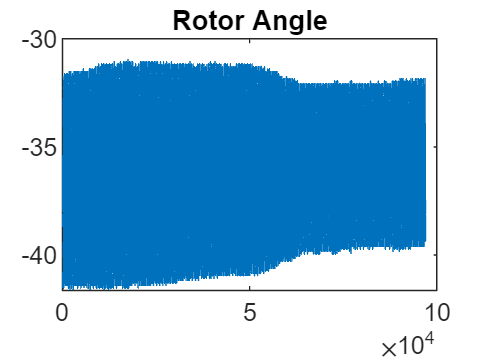

plot(y);
title("Rotor Angle")

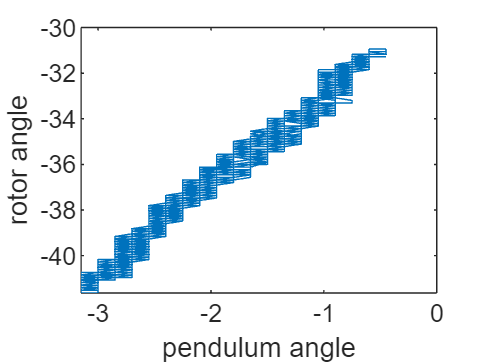

plot(x,y)
xlabel("pendulum angle")
ylabel("rotor angle")

Il sistema ha una frequenza d'oscillazione maggiore in quanto queste acquisizioni sono state effettuate con la fascetta nera la quale essendo più rigida, conferisce al sistema una Wn (rad k/m) maggiore.


for i=1:1000
    subplot(1,2,1)
    plot(x,[x(i+1:end) x(1:i)],'.');
    title("Pendulum Angle")
    subplot(1,2,2)
    plot(y,[y(i+1:end) y(1:i)],'.');
    title("Rotor Angle")
    if mod(i,10)==0
    pause
    end

end